clear
load('./traces_v5/input_sets_second_op.mat');

numberOfSets = 110;
setSize = 50;
%Get the mean traces by sets of 50
meanTraces = zeros(numberOfSets,size(traces_Y,2));

for i = 1 : numberOfSets
    meanTraces(i,:)=mean(traces_Y((i-1)*setSize+1:i*setSize,:),1);
end

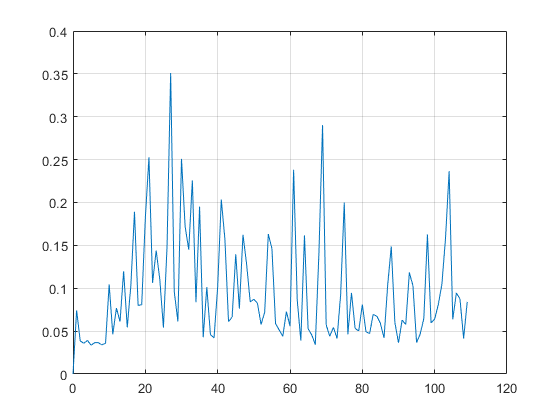


%Calculate euclidean distance with respect to the first average set trace
euclidDistances = zeros(1,numberOfSets);

for i = 1 : numberOfSets
    euclidDistances(i) = norm(meanTraces(1,:)-meanTraces(i,:));
end
plot(0:numberOfSets-1,euclidDistances)
grid on

Correlation ?

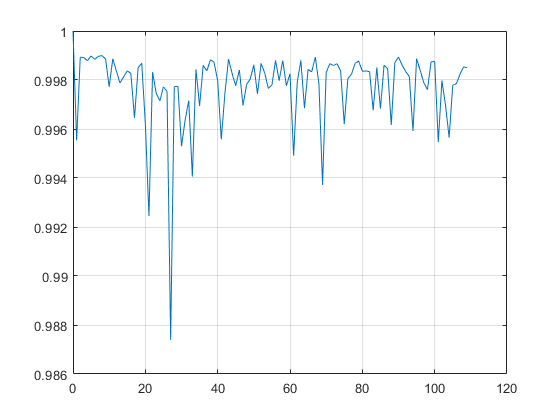

corrs = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    corr = corrcoef(meanTraces(1,:),meanTraces(i,:));
    corrs(i) = corr(1,2);
end
plot(0:numberOfSets-1,corrs)
grid on

Bounded collision detection criterion ?

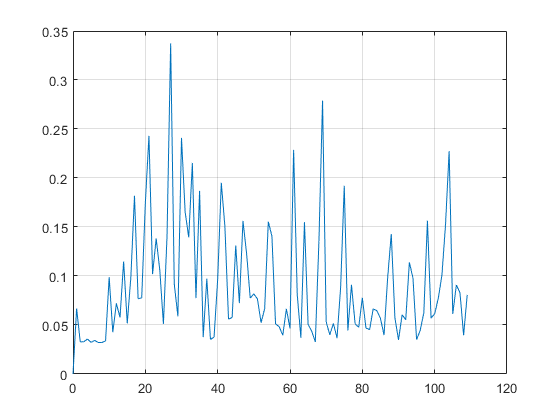

colDet = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    colDet(i) = bcdc(meanTraces(1,:),meanTraces(i,:));
end
plot(0:numberOfSets-1,colDet)
grid on

Use the filtered signal

%Get the mean traces by sets of 50
meanTraces2 = zeros(numberOfSets,size(traces_filt,2));

for i = 1 : numberOfSets
    meanTraces2(i,:)=mean(traces_filt((i-1)*setSize+1:i*setSize,:),1);
end

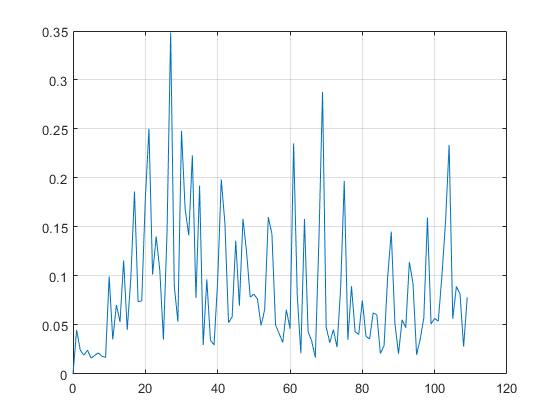

%Calculate euclidean distance with respect to the first average set trace
euclidDistances2 = zeros(1,numberOfSets);

for i = 1 : numberOfSets
    euclidDistances2(i) = norm(meanTraces2(1,:)-meanTraces2(i,:));
end
plot(0:numberOfSets-1,euclidDistances2)
grid on

Correlation ?

corrs2 = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    corr = corrcoef(meanTraces(1,:),meanTraces(i,:));
    corrs2(i) = corr(1,2);
end
plot(0:numberOfSets-1,corrs2)
grid on

Bounded collision detection criterion ?

colDet2 = zeros(1,numberOfSets);
for i = 1 : numberOfSets
    colDet2(i) = bcdc(meanTraces(1,:),meanTraces(i,:));
end
plot(0:numberOfSets-1,colDet2)
grid on